# robost tracking control (2m-class telescope)

clc;clear;
set(cstprefs.tbxprefs,'FrequencyUnits','Hz');

MODE = 'SIMU1'; %'SIMU1' OR 'SIMU2'

if strcmp(MODE,'SIMU1')
    load('data/disturb_extreme.mat');
    load('data/az_pre_SLine.mat');
else 
    if strcmp(MODE,'SIMU2')
        data = load('data/disturb_daven.mat');
        disturb = data.daven_filt*5;
        data = load('data/az_pre_satellite.mat');
        az_pre = data.az_pre;
    else
    error('Please choose a simulation')
    end
end

az_pre = az_pre - az_pre(1);
deltay = az_pre(2:end)-az_pre(1:end-1);

% 俯仰轴
vmax = 2;
amax = 0.5;
wsin = amax/vmax;
Asin = amax/(wsin^2);
Tsin = 2*pi/wsin;

% 系统参数
T_tol = 60;              % 仿真时长
Fs = 400;                % 仿真采样频率
Ts = 1/Fs;
T_simu = 0:1/Fs:T_tol;   % 仿真时间序列
k_tol = T_tol*Fs;        % 仿真总步数

% 电机、望远镜参数
L_dcm = 0.1;
R_dcm = 5;
C_dcm = 180/6*(30/pi);  % 反电动势系数 = 空载电压/最大空载转速
K_dcm = 200;        % 转矩系数 = 连续堵转转矩/电流
J_dcm = 110;
J_T = 70000;
fm = 0.1;         
fT = 1;      
kc = 7e5;

f_mode = sqrt(kc*(1/J_T+1/J_dcm))/2/pi;
disp(['望远镜的一阶谐振模态频率约为：', num2str(f_mode), ' Hz'])

望远镜的一阶谐振模态频率约为：12.7061 Hz



% 系统维数
nx = 5;     % 系统状态
ny = 1;     % 系统输出
nd = 1;     % 扰动输入
nu = 1;     % 控制输入
n1w = nx;   % 过程噪声
n2w = ny;   % 测量噪声
nXI = 1;    % /Xi
% 预见序列长度 simulation1 nr=5, simulation2 nr=8
if strcmp(MODE,'SIMU1')
    nr = 5;
else 
    if strcmp(MODE,'SIMU2')
        nr = 8;
    else
    error('Please choose a simulation')
    end
end

n_noise = nx+ny;                % 原系统总噪声（过程噪声+测量噪声）
nwa = n_noise + nd;             % 扩张扰动系统总噪声
nH = 2*nwa+nx+nd;           % 观测误差系统扰动（\varpi）
nw = nwa*2 + ny;              % 控制闭环系统扰动（ω_ξ）
nG = 2*nx + nd + ny + nr;     % 控制器李雅普诺夫函数矩阵

k_current = 1e2;
k_disturb = 1e7;
k_deg2rad = pi/180;

% 缩放系统量纲，电流i单位为1/k_current A，望远镜/电机转角单位为deg，扰动单位为1/k_disturb N·m
%               i                               wm              theta_m                   wt        theta_T
Asys0 = [-R_dcm/L_dcm                -C_dcm/L_dcm/k_current      0                       0           0;
        K_dcm/J_dcm*k_current       -fm/J_dcm                   -kc/J_dcm*k_deg2rad     0           kc/J_dcm*k_deg2rad;
        0                           1/k_deg2rad                 0                       0           0;
        0                           0                           kc/J_T*k_deg2rad      -fT/J_T       -kc/J_T*k_deg2rad;
        0                           0                           0                       1/k_deg2rad           0     ];
Bsys = [1/L_dcm/k_current*180/5 0 0 0 0]';
Csys = [0 0 0 0 1];                        % 测量/控制输出为 望远镜转角（deg）
Dsys = zeros(ny,nu);
Esys = [0 0 0 1/J_T*k_disturb 0]';         % 实际扰动输入

Ad = expm(Ts.*Asys0);
fun = @(x) expm(Asys0.*x);
q = integral(fun, 0, Ts, 'ArrayValued',true);
Bd = q*Bsys;
Ed = q*Esys;
Cd = Csys;
D1d = [eye(nx) zeros(nx,ny)];
D2d = [zeros(ny,nx) eye(ny)];

Ba = [Bd; 0];
Ca = [Cd 0];
D1a = [D1d zeros(nx,nd);zeros(nd,nx+nd) 1]*1e-3;
D2a = [D2d zeros(nd)]*1e-3;

J_T = 68843*1.05;
Asys = [-R_dcm/L_dcm                -C_dcm/L_dcm/k_current      0                       0           0;
        K_dcm/J_dcm*k_current       -fm/J_dcm                   -kc/J_dcm*k_deg2rad     0           kc/J_dcm*k_deg2rad;
        0                           1/k_deg2rad                 0                       0           0;
        0                           0                           kc/J_T*k_deg2rad      -fT/J_T       -kc/J_T*k_deg2rad;
        0                           0                           0                       1/k_deg2rad           0     ];
Ad1 = expm(Ts.*Asys);
Aa1 = [Ad1 Ed;zeros(nd,nx) eye(nd)];

J_T = 68843*0.95;
Asys = [-R_dcm/L_dcm                -C_dcm/L_dcm/k_current      0                       0           0;
        K_dcm/J_dcm*k_current       -fm/J_dcm                   -kc/J_dcm*k_deg2rad     0           kc/J_dcm*k_deg2rad;
        0                           1/k_deg2rad                 0                       0           0;
        0                           0                           kc/J_T*k_deg2rad      -fT/J_T       -kc/J_T*k_deg2rad;
        0                           0                           0                       1/k_deg2rad           0     ];
Ad2 = expm(Ts.*Asys);
Aa2 = [Ad2 Ed;zeros(nd,nx) eye(nd)];

deltaAd = zeros(nx,nx);
K_Ad = 0.1;
deltaAd(4,3) = K_Ad*Asys0(4,3)*Ts;
deltaAd(4,4) = K_Ad*Asys0(4,4)*Ts;
deltaAd(4,5) = K_Ad*Asys0(4,5)*Ts;

IC = [eye(nx+nd);Ca];
IC_pinv = pinv(IC,1e-4);
Y = [0 0 1 0 0 0 0]; 
TN = IC_pinv + Y*(eye(nx+ny+nd)-IC*IC_pinv);
T = TN(:,1:nx+nd)

T =     1.0000         0         0         0         0         0
         0    1.0000         0         0         0         0
         0         0    1.0000         0         0         0
         0         0         0    1.0000         0         0
         0         0         0         0    0.5000         0
         0         0         0         0         0    1.0000


N = TN(:,nx+nd+1:end);
TNC = T+N*Ca;

if rank(TNC)==size(T,1)
    disp('判断：T+NC等于单位阵');
else
    disp('判断：T+NC不为单位阵');
end

判断：T+NC等于单位阵


### 观测器LMI求解

yalmip('clear')

P = sdpvar(nx+nd,nx+nd,'symmetric');
Q = sdpvar(nx+nd,nx+nd,'full');
R1 = sdpvar(nx+nd,ny,'full');
R2 = sdpvar(nx+nd,ny,'full');
EPSILON = sdpvar(1,1);
GAMMA2 = sdpvar(1,1);

Uori = zeros(nx+nd);
k_UW = 1e-2;

Uori(4,3) = Asys0(4,3)*K_Ad*Ts/k_UW;
Uori(4,4) = Asys0(4,4)*K_Ad*Ts/k_UW;
Uori(4,5) = Asys0(4,5)*K_Ad*Ts/k_UW;
Wori = diag([0 0 1 1 1 0])*k_UW;

Uori*Wori

ans = 1.0e-04 *

         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0         0         0         0         0
         0         0    0.4363   -0.0000   -0.4363         0
         0         0         0         0         0         0
         0         0         0         0         0         0



U = Uori;
W = Wori;
WW = [zeros(nx+nd,nH-nx-nd) W]'*[zeros(nx+nd,nH-nx-nd) W];

M1 = [-P+eye(nx+nd)          zeros(nx+nd,nH)                     (Q*T*Aa1-R1*Ca)'                                zeros(nx+nd,nx+nd);
    zeros(nH,nx+nd)   -GAMMA2*eye(nH)+EPSILON*WW         [Q*T*D1a-R1*D2a -Q*N*D2a zeros(nx+nd,nx+nd)]' zeros(nH,nx+nd);
    Q*T*Aa1-R1*Ca        Q*T*D1a-R1*D2a -Q*N*D2a zeros(nx+nd)   P-Q-Q'                                      Q*T*U;
    zeros(nx+nd,nx+nd+nH)  (Q*T*U)'    -EPSILON*eye(nx+nd)]; 
M2 = P-eye(nx+nd);
M3 = GAMMA2*eye(nH)-EPSILON*WW;
M4 = [-P+eye(nx+nd)          zeros(nx+nd,nH)                     (Q*T*Aa2-R2*Ca)'                                zeros(nx+nd,nx+nd);
    zeros(nH,nx+nd)   -GAMMA2*eye(nH)+EPSILON*WW         [Q*T*D1a-R2*D2a -Q*N*D2a zeros(nx+nd,nx+nd)]' zeros(nH,nx+nd);
    Q*T*Aa2-R2*Ca        Q*T*D1a-R2*D2a -Q*N*D2a zeros(nx+nd)   P-Q-Q'                                      Q*T*U;
    zeros(nx+nd,nx+nd+nH)  (Q*T*U)'    -EPSILON*eye(nx+nd)]; 
LMIs = [M1<=0,M2>=0,M3>=0,M4<=0,EPSILON>=0, GAMMA2>=0];

opts = sdpsettings('solver','mosek');
opts.showprogress = 1;
diagno = optimize(LMIs,GAMMA2,opts)

+ Solver chosen : MOSEK-SDP
+ Processing objective function
+ Processing constraints
+ Calling Mosek

MOSEK Version 11.2.3 (Build date: 2026-8-19 02:34:21)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 71              
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 2               
  Matrix variables       : 4 (scalarized: 1713)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  -

diagno = 包含以下字段的 struct :
    yalmiptime: 0.0271
    solvertime: 0.1269
          info: 'Successfully solved (MOSEK)'
       problem: 0


if diagno.problem == 0
    disp('求解成功');
else
    disp(['求解出错！错误代码：', num2str(diagno.problem)]);
end

求解成功



check(LMIs)

 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|        4.3805e-09|      1.6832e-11|
|   #2|        Matrix inequality|           0.67207|      3.2114e-11|
|   #3|        Matrix inequality|        0.00095253|      7.1002e-07|
|   #4|        Matrix inequality|        5.8973e-09|      1.6655e-11|
|   #5|   Elementwise inequality|           17.4396|     -8.5543e-11|
|   #6|   Elementwise inequality|         0.0026965|      7.0979e-07|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 



P =double(P);
Q = double(Q);
R1 = double(R1);
R2 = double(R2);
L1 = Q\R1

L1 =    -0.0904
    0.4076
    0.2462
    3.5586
    0.7413
    0.9864


L2 = Q\R2

L2 =    -0.0902
    0.4074
    0.2464
    3.5579
    0.7412
    0.9864


EPSILON = double(EPSILON);
GAMMA2 = double(GAMMA2)

GAMMA2 = 0.0027


disp('观测误差系统闭环极点：');

观测误差系统闭环极点：


eig_obser1 = abs(eig(Aa1-L1*Ca))

eig_obser1 =     0.9129
    0.9129
    0.9741
    0.9741
    0.9300
    0.8918


if max(abs(eig(Aa1-L1*Ca)))>1
   disp('注意！系统不稳定！');
elseif max(abs(eig(Aa1-L1*Ca)))== 1
    disp('系统临界稳定');
else 
    disp('系统稳定');
end

系统稳定



eig_obser2 = abs(eig(Aa2-L2*Ca))

eig_obser2 =     0.9129
    0.9129
    0.9741
    0.9741
    0.9300
    0.8918


if max(abs(eig(Aa2-L2*Ca)))>1
   disp('注意！系统不稳定！');
elseif max(abs(eig(Aa2-L2*Ca)))== 1
    disp('系统临界稳定');
else 
    disp('系统稳定');
end

系统稳定


选取增广系统状态量$\xi \left(k\right)=\left\lbrack \begin{array}{c}
\Delta x_d \left(k\right)\\
e_c \left(k\right)\\
r^* \left(k\right)\\
\Delta e_o \left(k\right)
\end{array}\right\rbrack$

误差动态：


$$\xi \left(k+1\right)=\left(A_{\xi } +\Delta A_{\xi } \right)\xi \left(k\right)+B_{\xi } \Delta u\left(k\right)+D_{\xi } w_{\xi } \left(k\right)$$


$A_{\xi } =\left\lbrack \begin{array}{cccc}
A_d  &  &  & \\
-C_d  & I & C_r  & \\
 &  & A_r  & \\
 &  &  & A_a {-\textrm{LC}}_a 
\end{array}\right\rbrack$,$\Delta A_{\xi } =\left\lbrack \begin{array}{cccc}
{\Delta A}_d  &  &  & \\
 &  &  & \\
 &  &  & \\
\left\lbrack \begin{array}{c}
{\Delta A}_a \\
0
\end{array}\right\rbrack  &  &  & 
\end{array}\right\rbrack$,


$$B_{\xi } =\left\lbrack \begin{array}{c}
B_d \\
\\
\\

\end{array}\right\rbrack ,D_{\xi } =\left\lbrack \begin{array}{c}
\\
\\
D_r \\

\end{array}\right\rbrack$$


设计$\Delta u\left(k\right)=-M_x {\hat{x} }_d -M_d \hat{d} \left(k\right)-M_r r^* \left(k\right)-M_e e_c \left(k\right)$,


$$M_d =B_a^{\dagger} \left\lbrack \begin{array}{c}
E_d \\
0
\end{array}\right\rbrack$$


闭环误差动态：


$$\xi \left(k+1\right)=\left(A_{\textrm{cl}} +\Delta A_{\xi } \right)\xi \left(k\right)+D_{\xi } w_{\xi } \left(k\right)$$



$$\begin{array}{l}
A_{\textrm{cl}} =\left\lbrack \begin{array}{cccc}
A_d  &  &  & \\
-C_d  & I & C_r  & \\
 &  & A_r  & \\
 &  &  & A_a {-\textrm{LC}}_a 
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
B_d \\
\\
\\

\end{array}\right\rbrack \left\lbrack \begin{array}{cccc}
M_x  & M_e  & M_r  & -\left\lbrack \begin{array}{cc}
M_x  & B_d^{\dagger} E_d 
\end{array}\right\rbrack 
\end{array}\right\rbrack \\
=\left\lbrack \begin{array}{cccc}
A_d  &  &  & \\
-C_d  & I & C_r  & \\
 &  & A_r  & \\
 &  &  & A_a {-\textrm{LC}}_a 
\end{array}\right\rbrack -\left\lbrack \begin{array}{cccc}
B_d M_x  & B_d M_e  & B_d M_r  & \left\lbrack \begin{array}{cc}
{-B}_d M_x  & E_d 
\end{array}\right\rbrack \\
 &  &  & \\
 &  &  & \\
 &  &  & 
\end{array}\right\rbrack 
\end{array}$$


% 预见序列系统 系统矩阵
Ar = [zeros(nr-1,ny) eye(nr-1); zeros(ny,nr)];
Cr = zeros(ny,nr);
Cr(1:ny,1:ny) = eye(ny);
Dr = zeros(nr,ny);
Dr((end-ny+1):end,:) = eye(ny);


$$A_{\xi } =\left\lbrack \begin{array}{cccc}
A_d  &  &  & \\
-C_d  & I & C_r  & \\
 &  & A_r  & \\
 &  &  & A_a {-\textrm{LC}}_a 
\end{array}\right\rbrack$$


Axi1 = zeros(nG,nG);
Axi1(1:nx,1:nx) = Ad1;
Axi1(nx+ny,1:nx) = -Cd;
Axi1(nx+ny,nx+1:nx+ny) = eye(ny);
Axi1(nx+ny,(ny+nx+1):(nG-nx-nd)) = Cr;
Axi1((ny+nx+1):(ny+nx+nr),(ny+nx+1):(ny+nx+nr)) = Ar;
Axi1((nG-nx-nd+1):end,(nG-nx-nd+1):end) = Aa1-L1*Ca;
Axi1;

Axi2 = zeros(nG,nG);
Axi2(1:nx,1:nx) = Ad2;
Axi2(nx+ny,1:nx) = -Cd;
Axi2(nx+ny,nx+1:nx+ny) = eye(ny);
Axi2(nx+ny,(ny+nx+1):(nG-nx-nd)) = Cr;
Axi2((ny+nx+1):(ny+nx+nr),(ny+nx+1):(ny+nx+nr)) = Ar;
Axi2((nG-nx-nd+1):end,(nG-nx-nd+1):end) = Aa2-L2*Ca;
Axi2;


$$B_{\xi } =\left\lbrack \begin{array}{c}
B_d \\
\\
\\

\end{array}\right\rbrack$$


Bxi = [Bd; zeros(ny,nu);  zeros(nr+nx+nd,nu)];


$$D_{\xi } =\left\lbrack \begin{array}{ccc}
\left\lbrack \begin{array}{cc}
D_{1d}  & 
\end{array}\right\rbrack  &  & \\
-D_{2a}  &  & \\
 &  & D_r \\
H_1  & H_2  & 
\end{array}\right\rbrack$$


Dxi1 = zeros(nG,2*(nx+ny+nd)+ny);
Dxi1(1:nx,1:(nx+ny)) = D1a(1:nx,1:(nx+ny));
Dxi1((nx+1):(nx+ny),1:(nx+ny+nd)) = D2a;
Dxi1((ny+nx+1):(end-nx-nd),end) = Dr;

H1_1 = T*D1a - L1*D2a;
H2_1 = -N*D2a;
Dxi1((nx+ny+nr+1):end,1:end-ny) = [H1_1 H2_1];

Dxi1;

Dxi2 = zeros(nG,2*(nx+ny+nd)+ny);
Dxi2(1:nx,1:(nx+ny)) = D1a(1:nx,1:(nx+ny));
Dxi2((nx+1):(nx+ny),1:(nx+ny+nd)) = D2a;
Dxi2((ny+nx+1):(end-nx-nd),end) = Dr;

H1_2 = T*D1a - L2*D2a;
H2_2 = -N*D2a;
Dxi2((nx+ny+nr+1):end,1:end-ny) = [H1_2 H2_2];

Dxi2;

H无穷优化

H无穷性能函数：$J=\sum_{k=0}^{\infty } e_c^T \left(k\right)R_1 e_c \left(k\right)+\Delta u^T R_2 \Delta u\left(k\right)=\sum_{k=0}^{\infty } {z\left(k\right)}^T z\left(k\right)$

误差动态：


$$\left\lbrace \begin{array}{l}
\xi \left(k+1\right)=\left(A_{\xi } +\Delta A_{\xi } \right)\xi \left(k\right)+B_{\xi } \Delta u\left(k\right)+D_{\xi } w_{\xi } \\
z\left(k\right)=A_z \xi \left(k\right)+B_z \Delta u\left(k\right)
\end{array}\right.$$



$$A_z =\left\lbrack \begin{array}{c}
\sqrt{R_1 }C_{\xi } \\
0
\end{array}\right\rbrack ,B_z =\left\lbrack \begin{array}{c}
0\\
\sqrt{R_2 }
\end{array}\right\rbrack$$


LMI: $\Delta V_c \left(k\right)+{z\left(k\right)}^T z\left(k\right)-\gamma^2 {w_{\xi } \left(k\right)}^T w_{\xi } \left(k\right)\prec 0$

Cxi = [zeros(ny,nx) eye(ny) zeros(ny,nr+nx+nd)];

if strcmp(MODE,'SIMU1')
    R1 = 1.8e3;
    R2 = 1e-5;
else 
    if strcmp(MODE,'SIMU2')
        R1 = 15;
        R2 = 1e-5;
    else
    error('Please choose a simulation')
    end
end

Az = [R1*Cxi(:,1:nx+ny+nr); zeros(nu,nx+ny+nr)];
Bz = [zeros(ny,nu);R2];

yalmip('clear')

Almi1 = Axi1(1:nx+ny+nr,1:nx+ny+nr);
Almi2 = Axi2(1:nx+ny+nr,1:nx+ny+nr);
Blmi = Bxi(1:nx+ny+nr,:);
Clmi = Cxi(:,1:nx+ny+nr);
Dlmi1 = Dxi1(1:nx+ny+nr,:)*1e-3;
Dlmi2 = Dxi2(1:nx+ny+nr,:)*1e-3;

Ulmi = [Uori(1:nx,1:nx);zeros(ny+nr,nx)];
Wlmi = [Wori(1:nx,1:nx) zeros(nx,ny+nr)];

GAMMA2c = sdpvar(ny,ny,'full');
KAPPAinv = sdpvar(1,1,'full');
Ginv = sdpvar(nx+ny+nr,nx+ny+nr,'symmetric');
MGinv1 = sdpvar(nu,nx+ny+nr,'full');
MGinv2 = sdpvar(nu,nx+ny+nr,'full');
size_Mc1 = nx+ny+nr+nw+(nx+ny+nr)+nx+nx+ny+nu;
Mc1 = [-Ginv                     zeros(nx+ny+nr,nw)     (Almi1*Ginv - Blmi*MGinv1)'   zeros(nx+ny+nr,nx)  (Wlmi*Ginv)'        (Az*Ginv - Bz*MGinv1)';
       zeros(nw,nx+ny+nr)        -GAMMA2c*eye(nw)       Dlmi1'                       zeros(nw,nx)        zeros(nw,nx)        zeros(nw,ny+nu);
       Almi1*Ginv - Blmi*MGinv1    Dlmi1                   -Ginv                       KAPPAinv*Ulmi       zeros(nx+ny+nr,nx)  zeros(nx+ny+nr,ny+nu);
       zeros(nx,nx+ny+nr)        zeros(nx,nw)           KAPPAinv*Ulmi'              -KAPPAinv*eye(nx)   zeros(nx,nx)        zeros(nx,ny+nu);
       Wlmi*Ginv                 zeros(nx,nw)           zeros(nx,nx+ny+nr)          zeros(nx,nx)        -KAPPAinv*eye(nx)   zeros(nx,ny+nu);
       Az*Ginv - Bz*MGinv1        zeros(ny+nu,nw)        zeros(ny+nu,nx+ny+nr)       zeros(ny+nu,nx)     zeros(ny+nu,nx)     -eye(ny+nu)];
Mc2 = [-Ginv                     zeros(nx+ny+nr,nw)     (Almi2*Ginv - Blmi*MGinv2)'   zeros(nx+ny+nr,nx)  (Wlmi*Ginv)'        (Az*Ginv - Bz*MGinv2)';
       zeros(nw,nx+ny+nr)        -GAMMA2c*eye(nw)       Dlmi2'                       zeros(nw,nx)        zeros(nw,nx)        zeros(nw,ny+nu);
       Almi2*Ginv - Blmi*MGinv2    Dlmi2                  -Ginv                       KAPPAinv*Ulmi       zeros(nx+ny+nr,nx)  zeros(nx+ny+nr,ny+nu);
       zeros(nx,nx+ny+nr)        zeros(nx,nw)           KAPPAinv*Ulmi'              -KAPPAinv*eye(nx)   zeros(nx,nx)        zeros(nx,ny+nu);
       Wlmi*Ginv                 zeros(nx,nw)           zeros(nx,nx+ny+nr)          zeros(nx,nx)        -KAPPAinv*eye(nx)   zeros(nx,ny+nu);
       Az*Ginv - Bz*MGinv2        zeros(ny+nu,nw)        zeros(ny+nu,nx+ny+nr)       zeros(ny+nu,nx)     zeros(ny+nu,nx)     -eye(ny+nu)];

LMIcs = [Mc1<= -3e-9*eye(size_Mc1), Mc2<= -3e-9*eye(size_Mc1), Ginv>=0, GAMMA2c>=0, KAPPAinv>=0];

opts =  sdpsettings('solver','mosek');
diagno = optimize(LMIcs,GAMMA2c,opts)

MOSEK Version 11.2.3 (Build date: 2026-8-19 02:34:21)
Copyright (c) MOSEK ApS, Denmark WWW: mosek.com
Platform: Windows/64-X86

Problem
  Name                   :                 
  Objective sense        : minimize        
  Type                   : CONIC (conic optimization problem)
  Constraints            : 135             
  Affine conic cons.     : 0               
  Disjunctive cons.      : 0               
  Cones                  : 0               
  Scalar variables       : 2               
  Matrix variables       : 3 (scalarized: 3185)
  Integer variables      : 0               

Optimizer started.
Presolve started.
Linear dependency checker started.
Linear dependency checker terminated.
Eliminator started.
Freed constraints in eliminator : 0
Eliminator terminated.
Eliminator - tries                  : 1                 time                   : 0.00            
Lin. dep.  - tries                  : 1                 time                   : 0.00            
Lin. dep.  - pri

diagno = 包含以下字段的 struct :
    yalmiptime: 0.0228
    solvertime: 0.2202
          info: 'Successfully solved (MOSEK)'
       problem: 0


check(LMIcs);

 
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   ID|               Constraint|   Primal residual|   Dual residual|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
|   #1|        Matrix inequality|        2.1613e-10|      3.6192e-15|
|   #2|        Matrix inequality|        3.8898e-10|      3.5502e-15|
|   #3|        Matrix inequality|        1.5112e-05|      4.9759e-15|
|   #4|   Elementwise inequality|        0.00056293|      1.1977e-05|
|   #5|   Elementwise inequality|              2.19|      3.2288e-09|
+++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++++
 


KAPPAinv = value(KAPPAinv)

KAPPAinv = 2.1900

Mc1 = value(Mc1);
MGinv1 = value(MGinv1);
MGinv2 = value(MGinv2);
Ginv = value(Ginv);
GAMMA2c = value(GAMMA2c)

GAMMA2c = 5.6293e-04

Kc1 = MGinv1/Ginv;
Kc2 = MGinv2/Ginv;
Kc_all1 = [Kc1 -Kc1(1:nx) pinv(Bd)*Ed];
Kc_all2 = [Kc2 -Kc2(1:nx) pinv(Bd)*Ed];
abs(eig(Axi1-Bxi*Kc_all1))

ans =     0.0001
    0.6310
    0.6310
    0.7091
    0.7091
    0.6017
    0.9129
    0.9129
    0.9741
    0.9741


if max(abs(eig(Axi1-Bxi*Kc_all1)))>= 1
    disp('系统不稳定');
end

Aa = [Ad Ed;zeros(nd,nx) eye(nd)];
L = L1;
Kc = Kc1;

lp_f_MeasNoise = 8*2*pi;
lptf_MeasNoise = tf(1,[1/(lp_f_MeasNoise^2) 2/lp_f_MeasNoise 1]);
lptf_MeasNoise_d = c2d(lptf_MeasNoise,Ts);
[z_MN,p_MN,k_MN] = zpkdata(lptf_MeasNoise_d,'vector');

wc = 5*2*pi;
wo_ADRC = 150*2*pi;
beta = exp(-wo_ADRC*Ts);
b0 = 9;
A_esos = [1 Ts Ts^2/2;0 1 Ts; 0 0 1];
B_esos = [b0*Ts^2/2; b0*Ts; 0];
Lc_eso = [1-beta^3; (1-beta)^2*(1+beta)*3/2/Ts;(1-beta)^3/(Ts^2)];
Lp_eso = A_esos*Lc_eso;
C_esos = [1 0 0];
D_esos = 0;

A_eso = A_esos-Lp_eso*C_esos;
B_eso = [B_esos,Lp_eso];
C_eso = eye(3);
D_eso = zeros(3,2);

plant = ss(Ad,Bd,Cd,[],Ts);
opt = pidtuneOptions('DesignFocus','reference-tracking');
pid_p = pidtune(plant,'PIDF',4*2*pi,opt);
[z_pid,p_pid,k_pid] = zpkdata(pid_p,'vector');

load('data/ctrl_OF.mat');
[z_of,p_of,k_of] = zpkdata(C4,'vector');

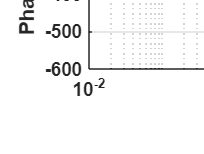

ss_ol = ss(Ad, Bd, Cd, 0, Ts);
ss_d2o = ss(Ad, Ed, Cd, 0, Ts);

freq_start = 1e-2;
freq_end = Fs/2 - 1e-3;
freq_bode = logspace(log10(freq_start), log10(freq_end), 1000);

[mag_ol,pha_ol, ]= bode(ss_ol, freq_bode*2*pi);
[mag_d2o,pha_d2o, ]= bode(ss_d2o, freq_bode*2*pi);

freq_res = logspace(log10(13), 2, 1000);
[mag_ol_res,~, ~ ]= bode(ss_ol, freq_res*2*pi);
[peak_mag, idx_peak] = max(mag_ol_res);
freq_res = freq_res(idx_peak);

label_mag = 'Magnitude (dB)';
label_pha = 'Phase (deg)';
figure()
t = tiledlayout(2,2,'Padding','tight', 'TileSpacing', 'compact');
t.Units = "centimeters";
t.OuterPosition = [0.5 0.5 14 10];
t.Position = [1.7 1.6 13 8];

nexttile;
bp1 = semilogx(freq_bode, 20*log10(mag_ol(:)),'DisplayName','Plant');
bp1.LineWidth = 2;
grid on;
xlim([freq_start, freq_end]);
ylabel(label_mag,'FontWeight','bold');
legend('FontSize', 9);
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 10;

f_res_floor = floor(freq_res);

xline(freq_res, 'k--', 'LineWidth', 1.2, ...
      'Label', sprintf('$f_{res}=%d$ Hz', f_res_floor), ...
      'LabelOrientation', 'horizontal', 'Interpreter', 'latex',...
      'LabelVerticalAlignment','bottom', ...
      'LabelHorizontalAlignment','center',...
      'HandleVisibility','off');

nexttile;
bp2 = semilogx(freq_bode, 20*log10(mag_d2o(:)),'k');
bp2.LineWidth = 2;
grid on;
xlim([freq_start, freq_end]);
legend('DTF');
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 10;

nexttile;
bp3 = semilogx(freq_bode, pha_ol(:));
bp3.LineWidth = 2;
grid on;
xlim([freq_start, freq_end]);
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 10;
ylabel(label_pha,'FontWeight','bold');

nexttile;
bp4 = semilogx(freq_bode, pha_d2o(:),'k');
bp4.LineWidth = 2;
grid on;
xlim([freq_start, freq_end]);
ax = gca; 
ax.FontWeight = 'bold';
ax.FontSize = 10;

xlabel(t, 'Frequency (Hz)','FontWeight','bold');

exportgraphics(gcf,fullfile('figures1', 'frequency_response.pdf'),'ContentType','vector');